## TOPIC 15: Working with text

ENGR105, 10/22/20

#### Practice problem: reactor cooling

Consider a reactor (e.g. a bioreactor, chemical reactor, nuclear reactor, etc.) that, due to some internal perturbation**, experiences a temporary increase in temperature right before **`t = 0`. The reactor itself is designed such that it is encased by a “barrier material” that serves to protect the wall of the reactor from a potentially caustic cooling fluid. This constantly flowing low temperature cooling fluid serves as a heat sink that should (hopefully!) keep the reactor at a sufficiently low temperature for the reaction to proceed safely and efficiently

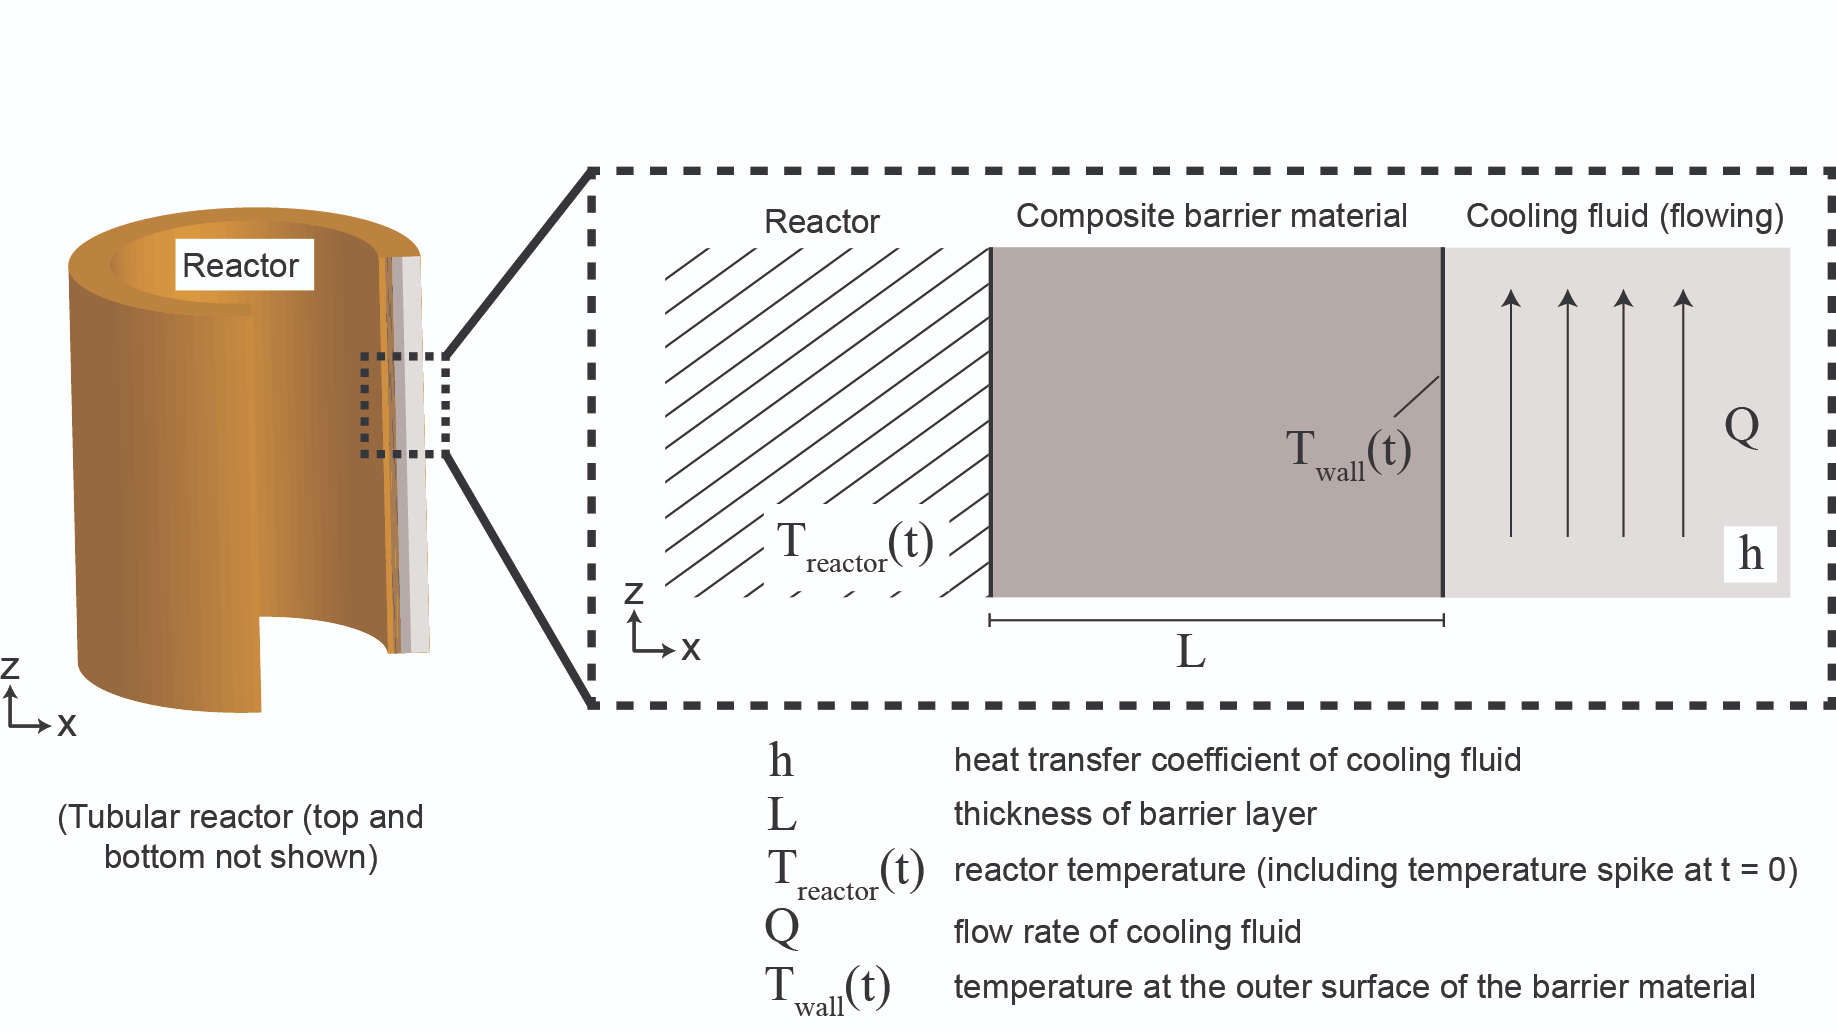

Assume you have already applied your knowledge of heat transport to quantitatively describe this system. **You have produced the following equation** that describes `T_wall`, the temperature of the outer surface of the barrier layer as a function of time, where the **time-dependency **(*i.e.* the shape of the curve) **is influenced by the heat transfer coefficient of the cooling fluid, **as well as many other system parameters.

**Issue**: `T_wall` (defined above) increases in temperature to above 400 degrees following the perturbation in the reactor. If `T_wall` remains greater than `400C` for more than some important length of time (*e.g.* 30 minutes), there is a significant risk of barrier layer degradation or some other adverse outcome.

**Your task as an engineer**: produce a MATLAB script that enables you to visualize how **the time required for **`T_wall` **to drop below 400C** (in the system described above) **depends on the cooling fluid heat transfer coefficient, **`h``.`

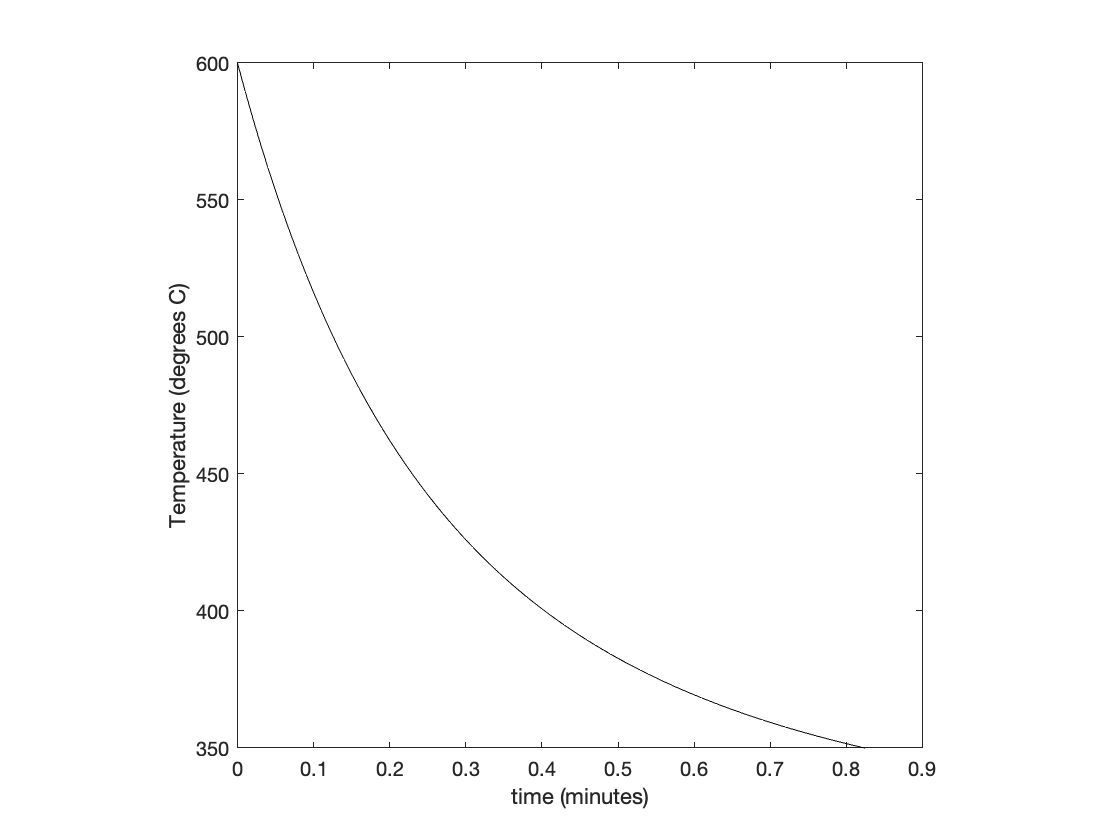


% Step 1: Plot the raw data -> can do so by plotting T_wall vs time
%create a vector for time 
t = 0:0.01:50;

Twall = @(h) 50*(1./(t+1) + 5*(t+1).^(-4*h)) + 300;

plot(t,Twall(1), 'k-')
axis square 
xlabel('time (minutes)')
ylabel('Temperature (degrees C)')
ylim([350,600])

%Step 2: specify ranges of h
%"relevant" -> determined from our system 
h = logspace(-2, 1, 200);

%preallocate the vector 
t400 = zeros(1,length(h))

t400 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


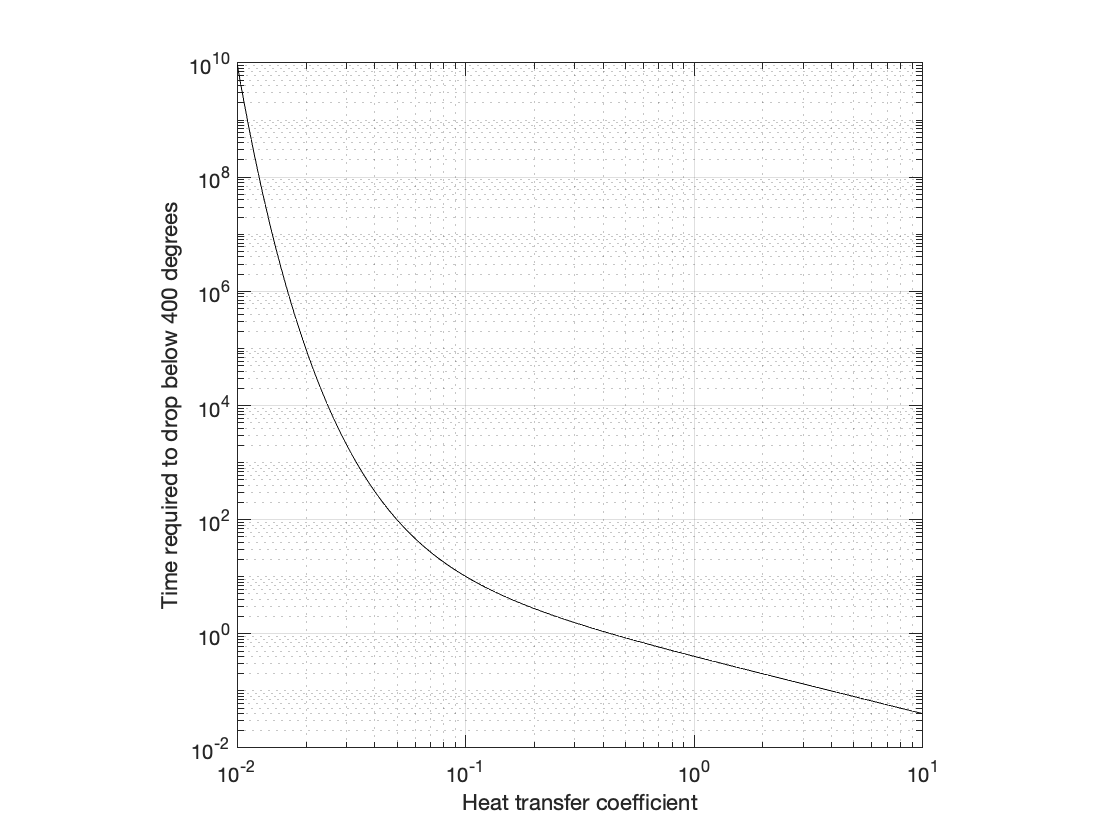


%Step 3: For each h value, solve for the cooling time 
for k = 1:length(h)
   %Step 4: Store cooling time in a vector so that we can produce a plot 
   t400(k) = newtonSolve(@(x) quiz3(x,h(k)),0,10^-4);  
end

% Step 5: Produce a plot to visualize how t400 depends on the heat transfer
% coefficient 
plot(h,t400,'k-')
%set graphical parameters
xlabel('Heat transfer coefficient')
ylabel('Time required to drop below 400 degrees')
axis square
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
set(gca, 'XMinorTick', 'on')
set(gca, 'TickLength', [0.02, 0.05])
grid on

**Question**: define `t400` as the time required for `T_wall` to drop to `400C` for a given value of `h`. **How can we solve for **`t400`**?**

There are (at least) two different potential philosophical approaches to solve this problem: 

**1) "Brute force" arrival at the solution **

- Calculate a large array of time points, determine the temperature at these points, then determine the first temperature that is less than 400C.

- Or, similarly, calculate the temperature at time zero after every small increment until the temperature drops below 400C.

*Example:*

**2) Use a numerical solver**

- Newton-Raphson: root-finding algorithm. Use iterative calculations until we converge at the root of an equation. 

*Example:* We have used this method a lot so far, and have already created a function to carry out this approach.

**For applications like this (well-behaved, arbitrary function): Newton-Raphson will generally work better than a brute force approach**

*This can be seen in two ways:*

**A)** Computational considerations -- how many "calculations" need to be performed for each approach. We can depict this visually by plotting the data point following each iteration

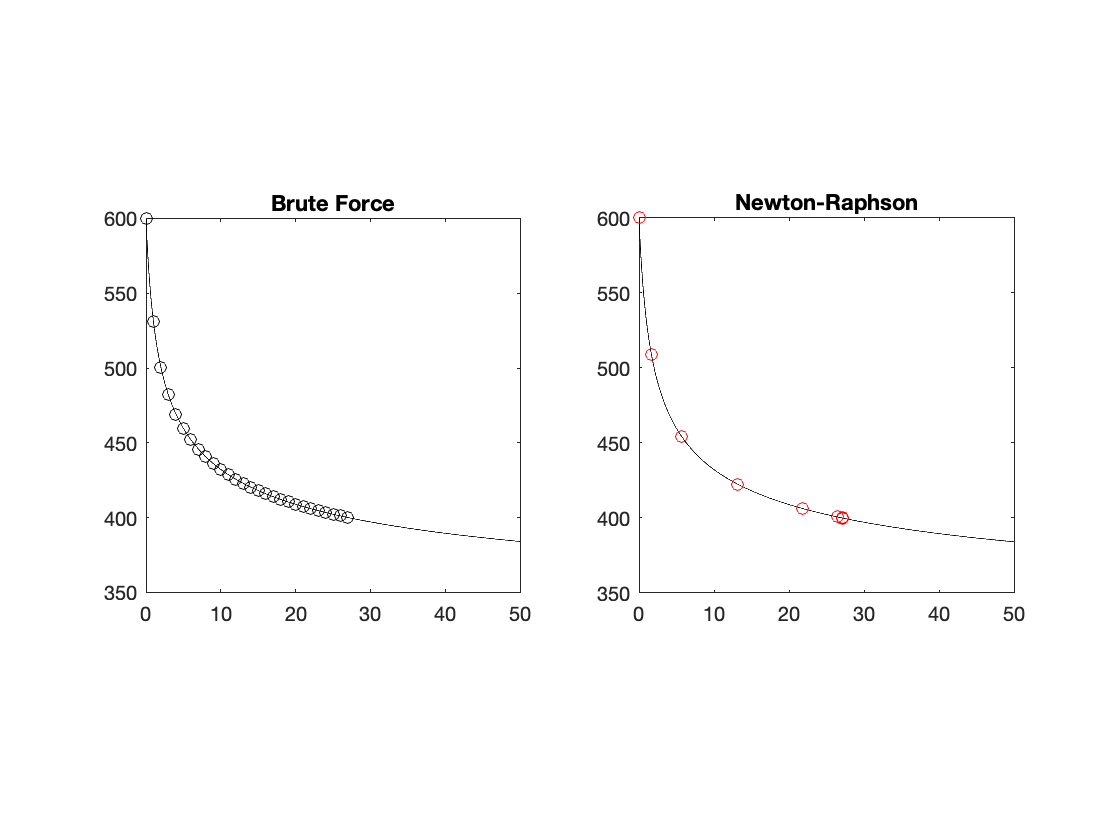

% Heat transfer coefficient to consider
h1 = 0.07;

% Temperature
T_wall = @(h) 50*(1./(t+1) + 5*(t+1).^(-4*h)) + 300;

% FIRST Subplot: Brute Force approach
subplot(1,2,1)

% Temperature profile corresponding to tested heat transfer coefficient
TempH1 = T_wall(h1);

% Simulate "brute force" approach
t_BF = t(TempH1 > 400);
TempH2 = TempH1(TempH1 > 400);

% Plot temperature profile
plot(t,TempH1,'k-')
hold on
% Plot brute force calculations
plot(t_BF(1:100:end),TempH2(1:100:end),'ko')
hold off
axis square
title('Brute Force')


% SECOND Subplot: Newton-Raphson
subplot(1,2,2)

% Simulate Newton-Raphson:
% Determine t values for each iteration
t_NRiterations = newtonSolveReturnXvalues(@(x) quiz3(x,h1),0,10^-4);
% Determine corresponding temperature value
T_NR = 50*(1./(t_NRiterations+1) + 5*(t_NRiterations+1).^(-4*h1)) + 300;

% Plot temperature profile
plot(t,TempH1,'k-')
hold on
% Plot each NR iteration
plot(t_NRiterations,T_NR,'ro')
hold off
axis square
title('Newton-Raphson')

**Takeaway**: Newton-Raphson "finds" the solution in **fewer iterations** at a **higher precision** (stricter tolerance).

**B)** Memory considerations -- Newton-Raphson requires substantially fewer resources. In the above example, note that vectors (`t1` and `T`) each require >400MB of memory!

**Other common themes and issues in Quiz 3**

1) Uncertainty about `for` loop notation and indexing / not preallocating

close all % Close above plots
% Goal: perform some operation on each entry of the vector h.
% Declare vector of heat transfer coefficients
h = 1:0.1:10;
% Use a FOR loop, do some operation on each element of h and store the
% output in the corrsponding entry in some other vector
t_out = [];
for k = h
    t_out(end+1) = k^2;
end

This could be rewritten using **array preallocation**:

% Use a FOR loop, do some operation on each element of h and store the
% output in the corrsponding entry in some other vector
t_out = zeros(1,length(h));
for k = 1:length(h)
    t_out(k) = h(k)^2;
end

2) Newton Raphson / root-finding

Recall: N-R is a root-finding algorithm. As such, it can only be used to solve for when some function evaluates to zero. This is not a problem though, as f(t) = a can be rewritten as g(t) = f(t) - a, which can be used with the Newton-Raphson method.

#### Reminder: characters and strings

MATLAB can process text as character arrays and strings. 

**Character arrays are distinguished by single quotes** (`'`).

a = 'k--';
b = 'LineWidth';
c = 'This is a character array';
disp(c)

This is a character array


**Strings are created using double quotes** (`"`).

s1 = "This is a string";
disp(s1)

This is a string


**Similarity**: both can be used to store text information

**Difference**: 

- Each character (including spaces and punctuation) in a character arrays corresponds to an index position in a "vector" or array.

- An entire string corresponds to one index position

% Index the above character array
c(1)

ans = 'T'

c(5:10)

ans = ' is a '

c(1:2:end)

ans = 'Ti sacaatrary'

% Use vector operations to determine the number of characters (including
% spaces) in a piece of text.
length(c)

ans = 25

% Use indexing on string. NOTE: only ONE element of s1
s1(1)

ans = "This is a string"

**Thus**: character arrays enable you to retrieve and manipulate each character in a piece of text, while strings treat the entire "block" of text as one unit.

#### Reminder: cell arrays

Cell arrays are arrays with indices that can hold a variety of data types or sizes - **all in the same variable**. Use `{}` to refer to cell contents and `()` to refer to the container.

% Create cell array
C = {'it is Thursday', [1 5 9], [2 3 1; 5 9 7], ...
    uint8([1 4]), [.5; .1; .9], {'hello',[1 5]}}

C = 1×6 cell array
    {'it is Thursday'}    {1×3 double}    {2×3 double}    {1×2 uint8}    {3×1 double}    {1×2 cell}


% Reference the cell container
C(1)

ans = 1×1 cell array
    {'it is Thursday'}


% Reference the contents of a particular cell
Str = C{1}

Str = 'it is Thursday'

% The contents could then be processed
Str(1:9 )

ans = 'it is Thu'

### Working with text

The ability to work with and manipulate text is important in many different applications: both those that *explicitly* deal with text data (e.g. studying genomic data) and those that involve numerical data but have some *text identifier* (e.g. batch processing of data files, images, etc.).

#### Loading text

- `importdata() `reads in each line of text as a cell array index.

txt1 = importdata("TextData.txt");
disp(txt1)

    {'Hey Macklemore? can we go thrift shopping?'                                  }
    {'What, what, what, what'                                                      }
    {'What, what, what, what'                                                      }
    {'What, what, what, what'                                                      }
    {'What, what, what, what'                                                      }
    {'What, what, what, what'                                                      }
    {'What, what, what, what'                                                      }
    {'What, what, what, what'                                                      }
    {'What, what, what, what'                                                      }
    {'I'm gonna pop some tags'                                                     }
    {'Only got twenty dollars in my pocket'                                        }
    {'I, I, I'm hunting, looking for a come-up'                  

- Text files may be read into a workspace using `fileread``()`, which brings in the text as one long character string.

txt2 = fileread("TextData.txt")

txt2 =     'Hey Macklemore? can we go thrift shopping?
     What, what, what, what
     What, what, what, what
     What, what, what, what
     What, what, what, what
     What, what, what, what
     What, what, what, what
     What, what, what, what
     What, what, what, what
     I'm gonna pop some tags
     Only got twenty dollars in my pocket
     I, I, I'm hunting, looking for a come-up
     This is frickin awesome
     Nah walk up to the club like, what up, I got a big shirt!
     I'm just pumped, just bought some stuff from the thrift shop
     Ice on the fringe, it's so damn frosty
     The people like, Damn! That's a cold ass honkey.
     Rollin' in, hella deep, headin' to the mezzanine
     Dressed in all pink, 'cept my gator shoes, those are green
     Draped in a leopard mink, girls standin' next to me
     Probably shoulda washed this, smells like R. Kelly's sheets
     (Piss)
     But shoot, it was ninety-nine cents! (Bag it) Coppin' it, washin' it
     'Bout to go and g

disp(txt2)

Hey Macklemore? can we go thrift shopping?
What, what, what, what
What, what, what, what
What, what, what, what
What, what, what, what
What, what, what, what
What, what, what, what
What, what, what, what
What, what, what, what
I'm gonna pop some tags
Only got twenty dollars in my pocket
I, I, I'm hunting, looking for a come-up
This is frickin awesome
Nah walk up to the club like, what up, I got a big shirt!
I'm just pumped, just bought some stuff from the thrift shop
Ice on the fringe, it's so damn frosty
The people like, Damn! That's a cold ass honkey.
Rollin' in, hella deep, headin' to the mezzanine
Dressed in all pink, 'cept my gator shoes, those are green
Draped in a leopard mink, girls standin' next to me
Probably shoulda washed this, smells like R. Kelly's sheets
(Piss)
But shoot, it was ninety-nine cents! (Bag it) Coppin' it, washin' it
'Bout to go and get some compliments
Passin' up on those moccasins someone else's been walkin' in them
Bummy and grungy, f it man, I am stuntin'

Note the differences: `importdata` creates a **cell** array, `fileread` creates a **character** array.

size(txt1)

ans =     85     1


size(txt2)

ans =            1        3630


#### Character arrays

- **Storing consistent width character arrays**. Character arrays can be stored in a array-like format provided each **row is of the same length**.

M = ['hello' 'hi' ;'phone' 'it';'funny' 'oh']

M = 3×7 char array
    'hellohi'
    'phoneit'
    'funnyoh'


Concatenation errors will occur if all columns are not of equal length.

% F = ['mat' 'labs' ;'fun' 'times';'a' 'b']

- **Character arrays of variable width can be stored in cells.**

V = {'mat', 'labs' ;'fun' , 'times';'a', 'b'}

Individual lists of characters within the cell can then be accessed.

% Reference the text in the above cell array
c = V{2,1}

V = 3×2 cell array
    {'mat'}    {'labs' }
    {'fun'}    {'times'}
    {'a'  }    {'b'    }


% Note the indexing is the same as before. Above, we have a cell array in
% the format of a vector.
d = txt1{10}

c = 'fun'

**Note**: In practice, **character arrays are typically utilized to store vectors of characters** and these vectors are stored in cells

- Character vectors and arrays can be** indexed similarly as numeric arrays** and operated upon by many common array functions

% Using vector indexing to retrieve sub arrays of characters from the "d"
t1 = d(1)

d = 'I'm gonna pop some tags'

t2 = d(7)
t3 = d(1:2:end-2)
t4 = fliplr(d)

- Like numeric arrays, character array indices may be concatenated, replaced, and expanded

% Concatenate character arrays
d = [d,', yo']

t1 = 'I'

% Expand array

t2 = 'n'

d(end+1:end+5) = '. Woo'

t3 = 'Imgnappsm a'

% Delete entries

t4 = 'sgat emos pop annog m'I'

d([11:16,18:end-2]) = []

- Character arrays can use logical indexing

% Remove all spaces
d(d ~= ' ')

d = 'I'm gonna pop some tags, yo'

- Character arrays stored in cells may be indexed by **reference to cell** and **then array indices.**

% Create new character array
t1 = txt1{29}

d = 'I'm gonna pop some tags, yo. Woo'

% Create subarray
t2  = txt1{29}(1:11)

d = 'I'm gonna moo'

% Return character array containing all "r"s
t3 = txt1{29}(txt1{29} == 'r')

#### String arrays

String arrays can be formulated just like character arrays, except columns need not be of the same length - **each string** is viewed as a single index of data.

S = ["position", "velocity";...

ans = 'I'mgonnamoo'

    "acceleration","g-force"]
% Return the string in index position 1 (single index notation)
S(1)

**Note**: Because each string in a string array is viewed as a single index, any index can be replaced by a string without explicit reference to the indices of the characters

S(1,2) = "velocity in x"

t1 = 'No for real ask your grandpa can I have his hand-me-downs?'

S

**Note**: Because each string is viewed as a** single index**, a string array index **must be converted to a character array** in order to access specific characters.This can be done with the `char` function.

% Convert one entry into a character sub array

t2 = 'No for real'

c = char(S(2,1))
c = c(1:3)

t3 = 'rrrr'

#### Character and string functions

There are many high level functions to operate on character arrays and strings 

- `isletter()`: returns logical array indicating whether a particular character is a **letter** or not (**true**: that character is a letter).

c1 = txt1{39}

% Returns logical array indicating whether a particular character is a

S = 2×2 string array
    "position"        "velocity"
    "acceleration"    "g-force" 


% letter or not (true: that character is a letter)
v = isletter(c1)

ans = "position"

% Convert all to upper case
sU = upper(c1)
% Convert all to lower case

S = 2×2 string array
    "position"        "velocity in x"
    "acceleration"    "g-force"      


sL = lower(c1)

S = 2×2 string array
    "position"        "velocity in x"
    "acceleration"    "g-force"      


% Create a character array of spaces
sB = blanks(7)

- **Finding** a piece of text inside a character array

c1

c = 'acceleration'

% Create index at which word "dollars" appears

c = 'acc'

ind = strfind(c1, 'dollars')

**Note**: `strfind` is case-sensitive

% Create index at which word "Dollars" appears
ind = strfind(c1,'Dollars') 

c1 = 'Only got twenty dollars in my pocket'

- **Comparing** text

**Character arrays**. `strcmp``()`can be used to successfully evaluate if one character array is the same as another

if ~strcmp('twenty',c1)

v = 1×36 logical array
   1   1   1   1   0   1   1   1   0   1   1   1   1   1   1   0   1   1   1   1   1   1   1   0   1   1   0   1   1   0   1   1   1   1   1   1


    disp('yes')
end

sU = 'ONLY GOT TWENTY DOLLARS IN MY POCKET'

**Strings**. Because strings (denoted by double quotation marks) are viewed as singular entities, they can be compared via decision even if they have differing lengths

if "owl" ~= "owls"

sL = 'only got twenty dollars in my pocket'

    disp('yes')
end

sB = '       '

#### Converting numbers to characters

`num2str() `can be used to convert numbers to characters for concatenation with other characters. 

- One situation where this can be useful: converting a loop index or counter into text.

% Assume: 10 image files are present in a folder and I want to easily
% open all of them. First: declare base file name
basefile = 'imageFile';

c1 = 'Only got twenty dollars in my pocket'

% Second: use a for loop to create text (that could be used to open each)
for k = 1:10

ind = 17

    disp([basefile,num2str(k),'.tif'])  
end

#### Practice Problem: analyzing song lyrics

Consider the data in `txt1`, imported above. How many words are in the 46-th line? What is the average word length?

%Step 1: Create variable with 46th of code from txt1


ind =

     []




%Step 2: Can use spaces to determine where the words are -> have an
%isletter function and an isspace function 
%This would determine where spaces are 

%Step 3: for space, assign "previous" letters to a cell storing words 

yes



%add space to front and end of character array 




yes


imageFile1.tif
imageFile2.tif
imageFile3.tif
imageFile4.tif
imageFile5.tif
imageFile6.tif
imageFile7.tif
imageFile8.tif
imageFile9.tif
imageFile10.tif


Q1: how many words are there?

Q2: What is the average word length?

**Functions stored at the end of the document.**

**Practice problem: Reactor cooling**

function xn = newtonSolve(F,xn,tol)
    % The purpose of this function is to apply the Newton-Raphson method to
    % solve any arbitrary function, specified in an input F.
    % Inputs:
    % F: function and derivative
    % x: initial guess
    % tol: specified tolerance

    % Step 1: specify initial guess
    % Input xn -> initial guess
    xprev = inf; % Variable to store previous xn value -> ensure it is 
               % not xn to enter while loop
    
    % Step 2: iterate until xn -> xn+1
    while abs(xn - xprev) > tol
        % Apply input function to algorithm. NOTE: first output is function
        % evaluated at xn, the second output is the derivative of the
        % function evaluated at xn
        f = F(xn);        
        
        % Instead of calculating the "next" x value, store the previous xn
        % value
        xprev = xn;
        
        % Step 3b: update xn to next value for the iteration
        xn = xn - f(1)/f(2);
    end
end


function xn = newtonSolveReturnXvalues(F,xn,tol)
    % The purpose of this function is to apply the Newton-Raphson method to
    % solve any arbitrary function, specified in an input F.
    % Inputs:
    % F: function and derivative
    % x: initial guess
    % tol: specified tolerance

    % Step 1: specify initial guess
    % Input xn -> initial guess
    xprev = inf; % Variable to store previous xn value -> ensure it is 
               % not xn to enter while loop
    
    % Step 2: iterate until xn -> xn+1
    while abs(xn(end) - xprev) > tol
        % Apply input function to algorithm. NOTE: first output is function
        % evaluated at xn, the second output is the derivative of the
        % function evaluated at xn
        f = F(xn(end));        
        
        % Instead of calculating the "next" x value, store the previous xn
        % value
        xprev = xn(end);
        
        % Step 3b: update xn to next value for the iteration
        xn(end+1) = xn(end) - f(1)/f(2);
    end
    
end

function G = quiz3(t,h)
    % These two equations represent a function and its derivative that can
    % be solved by 
    % G(1): function
    % G(2): derivative of function
    
    G(1) = 50*(1./(t+1) + 5*(t+1).^(-4*h)) + 300 - 400;
    G(2) = 50*(-1*(t+1).^-2 + 5*(-4*h)*(t+1).^(-4*h-1));
end


